% %% constant
% c=60;
% round=60;
% l_veh=7;
% 
% E1=9;
% E2=13;
% E3=5;
% 
% %parameter of ud
% 
% N_ud=3;
% v_ud=50;
% l_ud=1000;
% 
% mu_udo1=1600/3600;
% mu_udo2=1800/3600;
% mu_udo3=1500/3600;
% 
% be_udo1=0.33;
% be_udo2=0.34;
% be_udo3=0.33;
% 
% c_ud=N_ud*l_ud/l_veh;
% 
% max_tau_ud=c_ud*l_veh/(N_ud*v_ud*c/3600*1000);
% 
% %parameter of o1d
% 
% N_o1d=3;
% v_o1d=60;
% l_o1d=1000;
% 
% mu_o1du=1600/3600;
% mu_o1do3=1800/3600;
% mu_o1do2=1500/3600;
% 
% be_o1du=0.33;
% be_o1do2=0.34;
% be_o1do3=0.33;
% 
% c_o1d=N_o1d*l_o1d/l_veh;
% 
% max_tau_o1d=c_o1d*l_veh/(N_o1d*v_o1d*60/3600*1000);
% 
% 
% % time_varying "constant"
% ae_ud=[(1800+10*E1)*ones(1,20),...
%     (2100+10*E2)*ones(1,20),...
%     (2300+10*E3)*ones(1,round-40)]/3600; %a_enter_ud
% 
% ae_o1d=(2100+10*E1)*ones(1,round)/3600; %a_enter_o1d
% 
% c_do1=zeros(1,round); 
% for i=1:1:round
%     if i<=20
%         c_do1(i)=40+E1;
%     elseif i<=35
%         c_do1(i)=40+E1-2*(i-20);
%     elseif i<=45
%         c_do1(i)=10+E1;
%     else
%         c_do1(i)=10+E1+2*(i-45);
%     end
% end
% c_do1;
% 
% c_do2=c_do1-E2*ones(1,round);
% 
% c_do3=[(30-E3)*ones(1,30),...
%     (30+E3)*ones(1,round-30)];
% 
% c_du=[(40-E3)*ones(1,30),...
%     (40+E3)*ones(1,round-30)];
% 
% C=[ae_ud;ae_o1d;c_du;c_do1;c_do2;c_do3];
% 

% 
% %linear A_eq,b_eq,A,b
% 
% A_eq=zeros(60*31,60*31);
% b_eq=zeros(60*31,1);
% 
% for k=2:1:round
%     
%     A_eq(1+(k-1)*31,(1+(k-2)*31))=1;
%     A_eq(1+(k-1)*31,(11+(k-2)*31))=c;
%     A_eq(1+(k-1)*31,(17+(k-2)*31))=-c;
%     
%     A_eq(2+(k-1)*31,(2+(k-2)*31))=1;
%     A_eq(2+(k-1)*31,(12+(k-2)*31))=c;
%     A_eq(2+(k-1)*31,(18+(k-2)*31))=-c;
%     
%     A_eq((5+(k-1)*31),(5+(k-2)*31))=1;
%     A_eq((5+(k-1)*31),(3+(k-2)*31))=be_udo1;
%     A_eq((5+(k-1)*31),(25+(k-2)*31))=-1;
%     A_eq((6+(k-1)*31),(6+(k-2)*31))=1;
%     A_eq((6+(k-1)*31),(3+(k-2)*31))=be_udo2;
%     A_eq((6+(k-1)*31),(26+(k-2)*31))=-1;
%     A_eq((7+(k-1)*31),(7+(k-2)*31))=1;
%     A_eq((7+(k-1)*31),(3+(k-2)*31))=be_udo3;
%     A_eq((7+(k-1)*31),(27+(k-2)*31))=-1;
%     
%     A_eq((8+(k-1)*31),(8+(k-2)*31))=1;
%     A_eq((8+(k-1)*31),(4+(k-2)*31))=be_o1du;
%     A_eq((8+(k-1)*31),(28+(k-2)*31))=-1;
%     A_eq((9+(k-1)*31),(9+(k-2)*31))=1;
%     A_eq((9+(k-1)*31),(4+(k-2)*31))=be_o1do2;
%     A_eq((9+(k-1)*31),(29+(k-2)*31))=-1;
%     A_eq((10+(k-1)*31),(10+(k-2)*31))=1;
%     A_eq((10+(k-1)*31),(4+(k-2)*31))=be_o1do3;
%     A_eq((10+(k-1)*31),(30+(k-2)*31))=-1;
%     
%     b_eq(11+(k-1)*31)=ae_ud(k);
%     b_eq(12+(k-1)*31)=ae_o1d(k);
%     b_eq(13+(k-1)*31)=c_du(k);
%     b_eq(14+(k-1)*31)=c_do1(k);
%     b_eq(15+(k-1)*31)=c_do2(k);
%     b_eq(16+(k-1)*31)=c_do3(k);
%     
%     A_eq(17+(k-1)*31,25+(k-2)*31)=1;
%     A_eq(17+(k-1)*31,26+(k-2)*31)=1;
%     A_eq(17+(k-1)*31,27+(k-2)*31)=1;
%     A_eq(18+(k-1)*31,28+(k-2)*31)=1;
%     A_eq(18+(k-1)*31,29+(k-2)*31)=1;
%     A_eq(18+(k-1)*31,30+(k-2)*31)=1;
%     
%     A_eq(19+(k-1)*31,5+(k-2)*31)=1;
%     A_eq(19+(k-1)*31,6+(k-2)*31)=1;
%     A_eq(19+(k-1)*31,7+(k-2)*31)=1;
%     A_eq(20+(k-1)*31,8+(k-2)*31)=1;
%     A_eq(20+(k-1)*31,9+(k-2)*31)=1;
%     A_eq(20+(k-1)*31,10+(k-2)*31)=1;    
% end
% 
% A=zeros(6*3*(round+1),60*31);
% b=zeros(6*3*(round+1),1);
% 
% for k=1:1:round
%     
%     A(1+(k-1)*6*3,25+(k-1)*31)=1;
%     A(1+(k-1)*6*3,31+(k-1)*31)=-mu_udo1/c;
%     A(2+(k-1)*6*3,25+(k-1)*31)=1;
%     A(2+(k-1)*6*3,5+(k-1)*31)=-1/c;
%     A(2+(k-1)*6*3,3+(k-1)*31)=-be_udo1;
%     A(3+(k-1)*6*3,25+(k-1)*31)=1;
%     A(3+(k-1)*6*3,14+(k-1)*31)=-1/(2c);
%     
%     A(4+(k-1)*6*3,26+(k-1)*31)=1;
%     A(4+(k-1)*6*3,31+(k-1)*31)=-mu_udo2/c;
%     A(5+(k-1)*6*3,26+(k-1)*31)=1;
%     A(5+(k-1)*6*3,6+(k-1)*31)=-1/c;
%     A(5+(k-1)*6*3,3+(k-1)*31)=-be_udo2;
%     A(6+(k-1)*6*3,26+(k-1)*31)=1;
%     A(6+(k-1)*6*3,15+(k-1)*31)=-1/(2c);
%     
%     A(7+(k-1)*6*3,27+(k-1)*31)=1;
%     A(8+(k-1)*6*3,27+(k-1)*31)=1;
%     A(8+(k-1)*6*3,7+(k-1)*31)=-1/c;
%     A(8+(k-1)*6*3,3+(k-1)*31)=-be_udo3;
%     A(9+(k-1)*6*3,27+(k-1)*31)=1;
%     A(9+(k-1)*6*3,16+(k-1)*31)=-1/(2c);
%     
%     A(10+(k-1)*6*3,28+(k-1)*31)=1;
%     A(11+(k-1)*6*3,28+(k-1)*31)=1;
%     A(11+(k-1)*6*3,8+(k-1)*31)=-1/c;
%     A(11+(k-1)*6*3,4+(k-1)*31)=-be_o1du;
%     A(12+(k-1)*6*3,28+(k-1)*31)=1;
%     A(12+(k-1)*6*3,13+(k-1)*31)=-1/(2c);
%     
%     A(13+(k-1)*6*3,29+(k-1)*31)=1;
%     A(13+(k-1)*6*3,31+(k-1)*31)=-mu_o1do2;
%     A(14+(k-1)*6*3,29+(k-1)*31)=1;
%     A(14+(k-1)*6*3,9+(k-1)*31)=-1/c;
%     A(14+(k-1)*6*3,4+(k-1)*31)=-be_o1do2;
%     A(15+(k-1)*6*3,29+(k-1)*31)=1;
%     A(15+(k-1)*6*3,15+(k-1)*31)=-1/(2c);
%     
%     A(16+(k-1)*6*3,30+(k-1)*31)=1;
%     A(16+(k-1)*6*3,31+(k-1)*31)=-mu_o1do3;
%     A(17+(k-1)*6*3,30+(k-1)*31)=1;
%     A(17+(k-1)*6*3,10+(k-1)*31)=-1/c;
%     A(17+(k-1)*6*3,4+(k-1)*31)=-be_o1do3;
%     A(18+(k-1)*6*3,30+(k-1)*31)=1;
%     A(18+(k-1)*6*3,16+(k-1)*31)=-1/(2c);
%     
%     b(7+(k-1)*6*3)=mu_udo3;
%     b(10+(k-1)*6*3)=mu_oqdu;
%     b(13+(k-1)*6*3)=mu_o1do2;
%     b(16+(k-1)*6*3)=mu_o1do3;
%         
% end
% 
% fun=@(x) sum(x(31,[1:61]));
% 
% 

fun=@TTS_calculate_2;
options=optimoptions('fmincon','Algorithm','sqp');
options_2=optimoptions('fminunc','HessUpdate','dfp');
[x_1,fval_1]=fmincon(fun,15*ones(1,61),[],[],[],[],[],[],[],options)


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 6.100000e+03.



x_1 =    15.0000   27.7017   29.5397   23.3283   24.3388   30.6316   25.5730   30.5116   29.8876   29.8752   29.0865   28.0698   30.4868   24.7535   25.8683   25.0878   23.9621   24.0037   26.4056   27.3214   24.0010   24.5882   26.7663   29.5208   30.3601   29.7493   28.6661   27.7999   35.2511   30.9538   34.3628   39.9217   33.4467   35.4821   36.5253   25.4892   26.1815   21.6299   33.6263   27.0839   33.0236   35.8410   28.3533   25.0112   36.0028   34.8335   34.8099   33.9527   29.5226   35.3618


fval_1 = 7.5208e+05

[x_2,fval_2]=fmincon(fun,45*ones(1,61),[],[],[],[],[],[],[],options)


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 6.100000e+03.



x_2 =    45.0000   16.8258   24.7174   29.5756   24.2094   22.7165   28.1527   21.9580   24.6721   23.5346   18.2294   29.3023   22.6487   18.7208   32.6825   16.9752   29.0087   21.5475   13.7299   33.5962   12.6411   36.4436   24.9242   26.3654   28.5687   30.8504   27.2318   29.5735   33.3328   20.7231   31.8353   30.8828   42.3490   31.2990   26.9846   39.8040   34.6776   35.6828   24.5965   27.3288   24.5610   26.4701   37.1399   23.6882   24.5724   35.6312   37.8102   30.4411   32.1167   36.0163


fval_2 = 7.5537e+05

[x_3,fval_3]=fminunc(fun,15*ones(1,61),options_2)


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


x_3 =    15.0000   30.1768   29.9185   29.6602   29.4019   29.1436   28.8853   28.6271   28.3688   28.1105   27.8522   29.5532   29.7525   29.9518   30.1511   30.3504   30.5497   31.4114   30.3048   30.5564   30.9988   31.3952   29.2705   29.1486   29.0266   28.9047   29.0422   30.9537   33.5724   29.8592   27.9572   30.2798   31.6607   31.4759   27.5775   28.5062   29.2320   28.6381   28.0442   27.4504   26.8565   26.2835   30.4347   29.5772   28.7198   27.8623   33.7278   30.7279   30.2613   31.5356


fval_3 = 7.5224e+05

[x_4,fval_4]=fminunc(fun,30*ones(1,61),options_2)


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


x_4 =    30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   35.9059


fval_4 = 7.5210e+05


[TTS,y,x,z,m,s,u] = TTS_calculate_2(x_4)

TTS = 7.5210e+05

y = 	1.0e+04 *

         0    0.3980    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4358    0.4698    0.4766    0.4766    0.4766    0.4766    0.4804    0.4953    0.5222    0.5611    0.6119    0.6748    0.7497    0.8412    0.9506    1.0781    1.2056    1.3331    1.4605    1.5880    1.7155    1.8544    1.9899    2.1254    2.2609    2.3964    2.5140    2.6135    2.6950


x =          0   31.5000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   43.4667   44.6000   44.6000   44.6000   44.6000   45.2367   46.8733   49.5100   53.1467   57.7833   63.4200   70.0567   78.4583   88.8600  101.2617  113.6633  126.0650  138.4667  150.8683  163.2700  177.5844  191.3260  205.0677  218.8094  232.5510  244.2927  254.0344  261.7760
         0   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   35.6767   37.5200   40.3633   44.2067   49.0500   54.8933   61.7367   69.5800   78.4233   87.2667   96.1100  104.9533  113.7967  122.6400  131.4833  140.3267  149.1700  158.0133  166.8567  174.7000  181.5433  187

z =          0    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6194    0.6528    0.6528    0.6528    0.6528    0.6528    0.6528    0.6528    0.6528    0.6528
         0    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0

m =          0    0.1386    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1733    0.1982    0.2044    0.2044    0.2044    0.2044    0.2044    0.2044    0.2044    0.2044    0.2044    0.2044    0.1917    0.1750    0.1583    0.1583    0.1583    0.1583    0.1583    0.1583    0.1583    0.1583    0.1583    0.1583    0.1583    0.1750    0.1917    0.2083    0.2250
         0    0.1428    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.1785    0.2042    0.2106    0.2106    0.2106    0.2000    0.1833    0.1667    0.1500    0.1333    0.1167    0.1000    0.0833    0.0667    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0667    0.0833    0.1000    0

s =          0    0.4200    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.5250    0.6006    0.6194    0.6194    0.6194    0.6088    0.5922    0.5755    0.5588    0.5422    0.5255    0.5088    0.4794    0.4461    0.4128    0.4128    0.4128    0.4128    0.4128    0.4128    0.4142    0.4237    0.4237    0.4237    0.4237    0.4571    0.4904    0.5238    0.5571
         0    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5806    0.5665    0.5498    0.5332    0.5165    0.4998    0.4832    0.4665    0.4498    0.4332    0.4332    0.4332    0.4332    0.4332    0.4332    0.4332    0.4332    0.4332    0.4332    0.4332    0.4498    0.4665    0.4832    0

u =    30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   30.0000   35.9059   34.0204


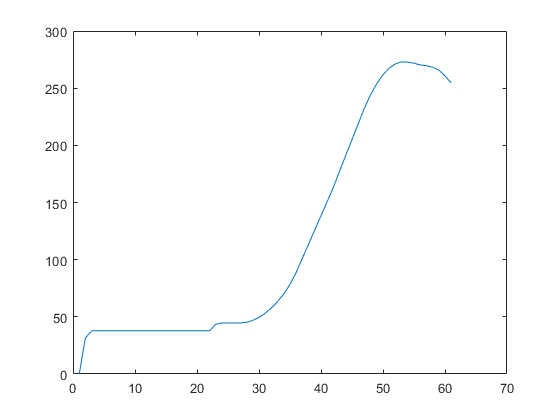

plot(x(1,:))

function y=computesquare(x)
    y=x(1).^2+x(2).^2;
end